TCSPC simulation data generation

Generate decays and IRF (Gaussian) using random number generators of exponential and Gaussian distribution respectively. Then bin the data in histogram (380 bins, 0-20ns)

%background count rate
bg = 10; %counts per s
%IRF width
irf_sigma = 1e-3; %ns
%Acquisition time
run_time = 20*60; %s 
%photon count rate is 2500 counts per s
n_photon = (2500-bg)*run_time; %no. of photons detected
%lifetimes from 0.2ns to 2 ns (step = 0.2ns)
%can define different arrays of tau
tau = linspace(0.2,2,10);
y = ones(n_photon,1);
[Tau,Y] = meshgrid(tau,y);
t0 = 10/19; %offset ns
%total time
t_tot = normrnd(t0,irf_sigma,size(Tau)) + exprnd(Tau);
edges = 0:1/19:20;

%2D array to store Intensity curves (row) of different lifetimes (col)
histCounts = zeros(numel(edges)-1, size(t_tot, 2));

for col = 1:size(t_tot, 2)
    histCounts(:, col) = histcounts(t_tot(:, col), edges);
end
t = edges(1,1:end-1)'%time-axis

t =          0
    0.0526
    0.1053
    0.1579
    0.2105
    0.2632
    0.3158
    0.3684
    0.4211
    0.4737


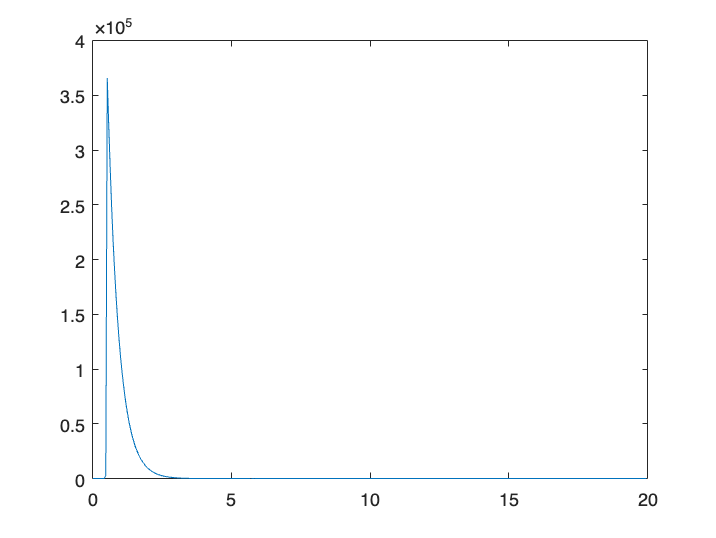

clf %clear figure 
plot(t,histCounts(:,2));

%fit(edges(1,60:end-1)',histCounts(60:end,2),'exp1')

Export generated data

csvwrite('decay_data/mono_exp.csv',histCounts)

Deconvolution

kernel = normpdf(t, t0, irf_sigma);  % Gaussian kernel (IRF)
y = histCounts(1:end,5);

y =            0
           0
           0
           0
           0
           0
           0
           0
           0
        1182


plot(t,ifft(fft(y)/fft(kernel))*sum(kernel))